clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[5.468;4.616;0.961];
u31=[0.9998;-0.00688;0.0175];
r2=[5.087;0.439;5.810];
u32=[0.9998;0.00688;0.0175];
r3=[14.862;2.088;0.961];
u33=[0.9998;-0.00688;0.0175];
r4=[14.481;2.967;5.810];
u34=[0.9998;0.00688;0.0175];
r5=[15.242;2.967;-3.889];
u35=[0.9998;0.00688;0.0175];
r6=[5.468;9.671;0.961];
u36=[0.9998;-0.00688;0.0175];
r7=[5.087;5.494;5.810];
u37=[0.9998;0.00688;0.0175];
r8=[14.862;7.143;0.961];
u38=[0.9998;-0.00688;0.0175];
r9=[14.481;8.022;5.810];
u39=[0.9998;0.00688;0.0175];
r10=[15.242;8.022;-3.889];
u310=[0.9998;0.00688;0.0175];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];

hold on
axis([0 15 0 15]);
for R3=2:0.3:13 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     3.2000    2.0000    1.0069


ans =     3.2000    2.3000    1.0056


ans =     3.2000    2.6000    1.0047


ans =     3.2000    2.9000    1.0040


ans =     3.2000    3.2000    1.0035


ans =     3.2000    3.5000    1.0032


ans =     3.2000    3.8000    1.0029


ans =     3.2000    4.1000    1.0027


ans =     3.2000    4.4000    1.0025


ans =     3.2000    4.7000    1.0024


ans =     3.2000    5.0000    1.0023


ans =     3.2000    5.3000    1.0022


ans =     3.2000    5.6000    1.0021


ans =     3.2000    5.9000    1.0020


ans =     3.2000    6.2000    1.0019


ans =     3.2000    6.5000    1.0019


ans =     3.2000    6.8000    1.0018


ans =     3.2000    7.1000    1.0018


ans =     3.2000    7.4000    1.0017


ans =     3.2000    7.7000    1.0017


ans =     3.2000    8.0000    1.0016


ans =     3.2000    8.3000    1.0016


ans =     3.2000    8.6000    1.0016


ans =     3.2000    8.9000    1.0015


ans =     3.2000    9.2000    1.0015


ans =     3.2000    9.5000    1.0015


ans =     3.2000    9.8000    1.0015


ans =     3.2000   10.1000    1.0014


ans =     3.2000   10.4000    1.0014


ans =     3.2000   10.7000    1.0014


ans =     3.2000   11.0000    1.0014


ans =     3.2000   11.3000    1.0013


ans =     3.2000   11.6000    1.0013


ans =     3.2000   11.9000    1.0013


ans =     3.2000   12.2000    1.0013


ans =     3.2000   12.5000    1.0013


ans =     3.2000   12.8000    1.0012



 scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')

for R1=2:0.3:13 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3];   
end

ans =     2.0000    5.9500    1.0063


ans =     2.3000    5.5500    1.0068


ans =     2.6000    5.3000    1.0135


ans =     2.9000    5.1500    1.0158


ans =     3.2000    5.0500    1.0168


ans =     3.5000    5.0000    1.0098


ans =     3.8000    4.9500    1.0090


ans =     4.1000    4.9000    1.0126


ans =     4.4000    4.9000    1.0007


ans =     4.7000    4.8500    1.0100


ans =     5.0000    4.8500    1.0020


ans =     5.3000    4.8000    1.0150


ans =     5.6000    4.8000    1.0093


ans = 1×3
    5.9000    4.8000    1.0045


ans = 1×3
    6.2000    4.8000    1.0004


ans = 1×3
    6.5000    4.7500    1.0171


ans = 1×3
    6.8000    4.7500    1.0140


ans = 1×3
    7.1000    4.7500    1.0113


ans = 1×3
    7.4000    4.7500    1.0089


ans = 1×3
    7.7000    4.7500    1.0067


ans = 1×3
    8.0000    4.7500    1.0048


ans = 1×3
    8.3000    4.7500    1.0031


ans = 1×3
    8.6000    4.7500    1.0016


ans = 1×3
    8.9000    4.7500    1.0002


ans = 1×3
    9.2000    4.7000    1.0200


ans = 1×3
    9.5000    4.7000    1.0189


ans = 1×3
    9.8000    4.7000    1.0178


ans = 1×3
   10.1000    4.7000    1.0169


ans = 1×3
   10.4000    4.7000    1.0161


ans = 1×3
   10.7000    4.7000    1.0153


ans = 1×3
   11.0000    4.7000    1.0145


ans = 1×3
   11.3000    4.7000    1.0139


ans = 1×3
   11.6000    4.7000    1.0133


ans = 1×3
   11.9000    4.7000    1.0127


ans = 1×3
   12.2000    4.7000    1.0122


ans = 1×3
   12.5000    4.7000    1.0117


ans = 1×3
   12.8000    4.7000    1.0112



scatter(x2,y2,10,'markerfacecolor',[29, 50, 67]/256,...
        'markeredgecolor',[29, 50, 67]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','13')

for R1=3:0.3:13 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];   
end

ans = 1×3
    3.0000    8.1000    1.0020


ans = 1×3
    3.3000    6.9000    1.0020


ans = 1×3
    3.6000    6.2500    1.0065


ans = 1×3
    3.9000    5.9000    1.0006


ans = 1×3
    4.2000    5.6000    1.0100


ans = 1×3
    4.5000    5.4500    1.0017


ans = 1×3
    4.8000    5.3000    1.0047


ans = 1×3
    5.1000    5.2000    1.0026


ans = 1×3
    5.4000    5.1000    1.0073


ans = 1×3
    5.7000    5.0500    1.0013


ans = 1×3
    6.0000    4.9500    1.0159


ans = 1×3
    6.3000    4.9000    1.0172


ans = 1×3
    6.6000    4.9000    1.0034


ans = 1×3
    6.9000    4.8500    1.0092


ans = 1×3
    7.2000    4.8000    1.0170


ans = 1×3
    7.5000    4.8000    1.0076


ans = 1×3
    7.8000    4.7500    1.0183


ans = 1×3
    8.1000    4.7500    1.0109


ans = 1×3
    8.4000    4.7500    1.0043


ans = 1×3
    8.7000    4.7000    1.0179


ans = 1×3
    9.0000    4.7000    1.0126


ans = 1×3
    9.3000    4.7000    1.0077


ans = 1×3
    9.6000    4.7000    1.0033


ans = 1×3
    9.9000    4.6500    1.0195


ans = 1×3
   10.2000    4.6500    1.0158


ans = 1×3
   10.5000    4.6500    1.0125


ans = 1×3
   10.8000    4.6500    1.0094


ans = 1×3
   11.1000    4.6500    1.0065


ans = 1×3
   11.4000    4.6500    1.0039


ans = 1×3
   11.7000    4.6500    1.0015


ans = 1×3
   12.0000    4.6000    1.0201


ans = 1×3
   12.3000    4.6000    1.0180


ans = 1×3
   12.6000    4.6000    1.0161


ans = 1×3
   12.9000    4.6000    1.0143



scatter(x3,y3,10,'markerfacecolor',[63, 125, 162]/256,...
        'markeredgecolor',[63, 125, 162]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','14')

for R1=3:0.3:13 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];   
end

ans = 1×3
    3.0000   10.2000    1.0012


ans = 1×3
    3.3000    8.0500    1.0031


ans = 1×3
    3.6000    7.1000    1.0041


ans = 1×3
    3.9000    6.5500    1.0059


ans = 1×3
    4.2000    6.2000    1.0061


ans = 1×3
    4.5000    5.9500    1.0075


ans = 1×3
    4.8000    5.8000    1.0005


ans = 1×3
    5.1000    5.6500    1.0034


ans = 1×3
    5.4000    5.5500    1.0011


ans = 1×3
    5.7000    5.4500    1.0048


ans = 1×3
    6.0000    5.3500    1.0136


ans = 1×3
    6.3000    5.3000    1.0111


ans = 1×3
    6.6000    5.2500    1.0115


ans = 1×3
    6.9000    5.2000    1.0143


ans = 1×3
    7.2000    5.2000    1.0023


ans = 1×3
    7.5000    5.1500    1.0086


ans = 1×3
    7.8000    5.1000    1.0167


ans = 1×3
    8.1000    5.1000    1.0083


ans = 1×3
    8.4000    5.1000    1.0009


ans = 1×3
    8.7000    5.0500    1.0121


ans = 1×3
    9.0000    5.0500    1.0060


ans = 1×3
    9.3000    5.0500    1.0005


ans = 1×3
    9.6000    5.0000    1.0141


ans = 1×3
    9.9000    5.0000    1.0095


ans = 1×3
   10.2000    5.0000    1.0054


ans = 1×3
   10.5000    5.0000    1.0016


ans = 1×3
   10.8000    4.9500    1.0171


ans = 1×3
   11.1000    4.9500    1.0139


ans = 1×3
   11.4000    4.9500    1.0110


ans = 1×3
   11.7000    4.9500    1.0082


ans = 1×3
   12.0000    4.9500    1.0057


ans = 1×3
   12.3000    4.9500    1.0033


ans = 1×3
   12.6000    4.9500    1.0011


ans = 1×3
   12.9000    4.9000    1.0187



 scatter(x4,y4,10,'markerfacecolor',[239, 193, 48]/256,...
        'markeredgecolor',[239, 193, 48]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','15')

for R3=3:0.3:13 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];   
end

ans = 1×3
    2.5000    3.0000    1.0221


ans = 1×3
    2.5000    3.3000    1.0221


ans = 1×3
    2.5000    3.6000    1.0221


ans = 1×3
    2.5000    3.9000    1.0221


ans = 1×3
    2.5000    4.2000    1.0221


ans = 1×3
    2.5000    4.5000    1.0221


ans = 1×3
    2.5000    4.8000    1.0221


ans = 1×3
    2.5000    5.1000    1.0221


ans = 1×3
    2.5000    5.4000    1.0221


ans = 1×3
    2.5000    5.7000    1.0221


ans = 1×3
    2.5000    6.0000    1.0221


ans = 1×3
    2.5000    6.3000    1.0221


ans = 1×3
    2.5000    6.6000    1.0221


ans = 1×3
    2.5000    6.9000    1.0221


ans = 1×3
    2.5000    7.2000    1.0221


ans = 1×3
    2.5000    7.5000    1.0221


ans = 1×3
    2.5000    7.8000    1.0221


ans = 1×3
    2.5000    8.1000    1.0221


ans = 1×3
    2.5000    8.4000    1.0221


ans = 1×3
    2.5000    8.7000    1.0221


ans = 1×3
    2.5000    9.0000    1.0221


ans = 1×3
    2.5000    9.3000    1.0221


ans = 1×3
    2.5000    9.6000    1.0221


ans = 1×3
    2.5000    9.9000    1.0221


ans = 1×3
    2.5000   10.2000    1.0221


ans = 1×3
    2.5000   10.5000    1.0221


ans = 1×3
    2.5000   10.8000    1.0221


ans = 1×3
    2.5000   11.1000    1.0221


ans = 1×3
    2.5000   11.4000    1.0221


ans = 1×3
    2.5000   11.7000    1.0221


ans = 1×3
    2.5000   12.0000    1.0221


ans = 1×3
    2.5000   12.3000    1.0221


ans = 1×3
    2.5000   12.6000    1.0221


ans = 1×3
    2.5000   12.9000    1.0221



 scatter(x5,y5,10,'markerfacecolor',[151, 150, 159]/256,...
        'markeredgecolor',[151, 150, 159]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','16')


 for R3=3:0.3:13 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r7,R1,R3,u31,u37);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];   
end

ans = 1×3
    2.4500    3.0000    1.0162


ans = 1×3
    2.4500    3.3000    1.0158


ans = 1×3
    2.4500    3.6000    1.0155


ans = 1×3
    2.4500    3.9000    1.0152


ans = 1×3
    2.4500    4.2000    1.0150


ans = 1×3
    2.4500    4.5000    1.0149


ans = 1×3
    2.4500    4.8000    1.0147


ans = 1×3
    2.4500    5.1000    1.0146


ans = 1×3
    2.4500    5.4000    1.0145


ans = 1×3
    2.4500    5.7000    1.0145


ans = 1×3
    2.4500    6.0000    1.0144


ans = 1×3
    2.4500    6.3000    1.0143


ans = 1×3
    2.4500    6.6000    1.0143


ans = 1×3
    2.4500    6.9000    1.0142


ans = 1×3
    2.4500    7.2000    1.0142


ans = 1×3
    2.4500    7.5000    1.0142


ans = 1×3
    2.4500    7.8000    1.0141


ans = 1×3
    2.4500    8.1000    1.0141


ans = 1×3
    2.4500    8.4000    1.0141


ans = 1×3
    2.4500    8.7000    1.0141


ans = 1×3
    2.4500    9.0000    1.0140


ans = 1×3
    2.4500    9.3000    1.0140


ans = 1×3
    2.4500    9.6000    1.0140


ans = 1×3
    2.4500    9.9000    1.0140


ans = 1×3
    2.4500   10.2000    1.0140


ans = 1×3
    2.4500   10.5000    1.0140


ans = 1×3
    2.4500   10.8000    1.0140


ans = 1×3
    2.4500   11.1000    1.0139


ans = 1×3
    2.4500   11.4000    1.0139


ans = 1×3
    2.4500   11.7000    1.0139


ans = 1×3
    2.4500   12.0000    1.0139


ans = 1×3
    2.4500   12.3000    1.0139


ans = 1×3
    2.4500   12.6000    1.0139


ans = 1×3
    2.4500   12.9000    1.0139



 scatter(x6,y6,10,'markerfacecolor',[237, 125, 49]/256,...
        'markeredgecolor',[237, 125, 49]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','17')

 for R1=2:0.3:13 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r8,R1,R3,u31,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];   
end

ans = 1×3
    2.0000    6.1500    1.0025


ans = 1×3
    2.3000    5.6500    1.0071


ans = 1×3
    2.6000    5.4000    1.0030


ans = 1×3
    2.9000    5.2000    1.0131


ans = 1×3
    3.2000    5.1000    1.0094


ans = 1×3
    3.5000    5.0000    1.0165


ans = 1×3
    3.8000    4.9500    1.0135


ans = 1×3
    4.1000    4.9000    1.0154


ans = 1×3
    4.4000    4.9000    1.0022


ans = 1×3
    4.7000    4.8500    1.0104


ans = 1×3
    5.0000    4.8500    1.0015


ans = 1×3
    5.3000    4.8000    1.0137


ans = 1×3
    5.6000    4.8000    1.0074


ans = 1×3
    5.9000    4.8000    1.0021


ans = 1×3
    6.2000    4.7500    1.0177


ans = 1×3
    6.5000    4.7500    1.0137


ans = 1×3
    6.8000    4.7500    1.0103


ans = 1×3
    7.1000    4.7500    1.0072


ans = 1×3
    7.4000    4.7500    1.0046


ans = 1×3
    7.7000    4.7500    1.0022


ans = 1×3
    8.0000    4.7500    1.0001


ans = 1×3
    8.3000    4.7000    1.0191


ans = 1×3
    8.6000    4.7000    1.0174


ans = 1×3
    8.9000    4.7000    1.0159


ans = 1×3
    9.2000    4.7000    1.0145


ans = 1×3
    9.5000    4.7000    1.0133


ans = 1×3
    9.8000    4.7000    1.0121


ans = 1×3
   10.1000    4.7000    1.0111


ans = 1×3
   10.4000    4.7000    1.0102


ans = 1×3
   10.7000    4.7000    1.0093


ans = 1×3
   11.0000    4.7000    1.0085


ans = 1×3
   11.3000    4.7000    1.0078


ans = 1×3
   11.6000    4.7000    1.0071


ans = 1×3
   11.9000    4.7000    1.0064


ans = 1×3
   12.2000    4.7000    1.0059


ans = 1×3
   12.5000    4.7000    1.0053


ans = 1×3
   12.8000    4.7000    1.0048



 scatter(x7,y7,10,'markerfacecolor',[84, 130, 53]/256,...
        'markeredgecolor',[84, 130, 53]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','18')


for R1=3.3:0.3:13 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r9,R1,R3,u31,u39);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    [R1,R3,miu2]
    x8=[x8,R1];
    y8=[y8,R3];   
end

ans = 1×3
    3.3000    9.5000    1.0006


ans = 1×3
    3.6000    7.6500    1.0017


ans = 1×3
    3.9000    6.7500    1.0064


ans = 1×3
    4.2000    6.2500    1.0058


ans = 1×3
    4.5000    5.9000    1.0091


ans = 1×3
    4.8000    5.7000    1.0013


ans = 1×3
    5.1000    5.5000    1.0068


ans = 1×3
    5.4000    5.3500    1.0108


ans = 1×3
    5.7000    5.2500    1.0091


ans = 1×3
    6.0000    5.1500    1.0133


ans = 1×3
    6.3000    5.1000    1.0069


ans = 1×3
    6.6000    5.0500    1.0040


ans = 1×3
    6.9000    5.0000    1.0038


ans = 1×3
    7.2000    4.9500    1.0062


ans = 1×3
    7.5000    4.9000    1.0108


ans = 1×3
    7.8000    4.8500    1.0174


ans = 1×3
    8.1000    4.8500    1.0073


ans = 1×3
    8.4000    4.8000    1.0168


ans = 1×3
    8.7000    4.8000    1.0087


ans = 1×3
    9.0000    4.8000    1.0014


ans = 1×3
    9.3000    4.7500    1.0138


ans = 1×3
    9.6000    4.7500    1.0078


ans = 1×3
    9.9000    4.7500    1.0023


ans = 1×3
   10.2000    4.7000    1.0169


ans = 1×3
   10.5000    4.7000    1.0124


ans = 1×3
   10.8000    4.7000    1.0082


ans = 1×3
   11.1000    4.7000    1.0043


ans = 1×3
   11.4000    4.7000    1.0008


ans = 1×3
   11.7000    4.6500    1.0177


ans = 1×3
   12.0000    4.6500    1.0147


ans = 1×3
   12.3000    4.6500    1.0118


ans = 1×3
   12.6000    4.6500    1.0092


ans = 1×3
   12.9000    4.6500    1.0067



 scatter(x8,y8,10,'markerfacecolor',[47, 85, 151]/256,...
        'markeredgecolor',[47, 85, 151]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','19')

for R1=4:0.3:13 %离心率
    R3=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r10,R1,R3,u31,u310);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    [R1,R3,miu2]
    x9=[x9,R1];
    y9=[y9,R3];   
end

ans = 1×3
    4.0000    7.4000    1.0036


ans = 1×3
    4.3000    6.8000    1.0051


ans = 1×3
    4.6000    6.4000    1.0077


ans = 1×3
    4.9000    6.1500    1.0036


ans = 1×3
    5.2000    5.9500    1.0030


ans = 1×3
    5.5000    5.8000    1.0016


ans = 1×3
    5.8000    5.6500    1.0085


ans = 1×3
    6.1000    5.5500    1.0090


ans = 1×3
    6.4000    5.5000    1.0002


ans = 1×3
    6.7000    5.4000    1.0095


ans = 1×3
    7.0000    5.3500    1.0075


ans = 1×3
    7.3000    5.3000    1.0079


ans = 1×3
    7.6000    5.2500    1.0105


ans = 1×3
    7.9000    5.2000    1.0150


ans = 1×3
    8.2000    5.2000    1.0044


ans = 1×3
    8.5000    5.1500    1.0119


ans = 1×3
    8.8000    5.1500    1.0033


ans = 1×3
    9.1000    5.1000    1.0130


ans = 1×3
    9.4000    5.1000    1.0060


ans = 1×3
    9.7000    5.0500    1.0176


ans = 1×3
   10.0000    5.0500    1.0118


ans = 1×3
   10.3000    5.0500    1.0065


ans = 1×3
   10.6000    5.0500    1.0017


ans = 1×3
   10.9000    5.0000    1.0157


ans = 1×3
   11.2000    5.0000    1.0116


ans = 1×3
   11.5000    5.0000    1.0078


ans = 1×3
   11.8000    5.0000    1.0043


ans = 1×3
   12.1000    5.0000    1.0010


ans = 1×3
   12.4000    4.9500    1.0170


ans = 1×3
   12.7000    4.9500    1.0142


ans = 1×3
   13.0000    4.9500    1.0116


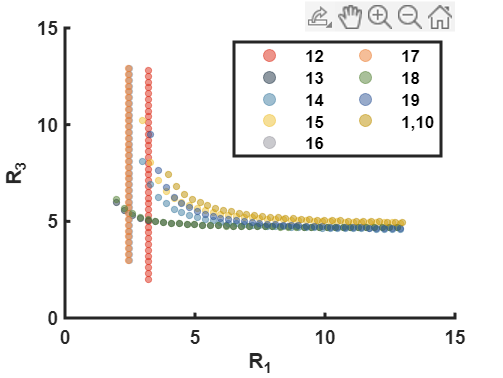


 scatter(x9,y9,10,'markerfacecolor',[191, 144, 0]/256,...
        'markeredgecolor',[191, 144, 0]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','1,10')




set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end
